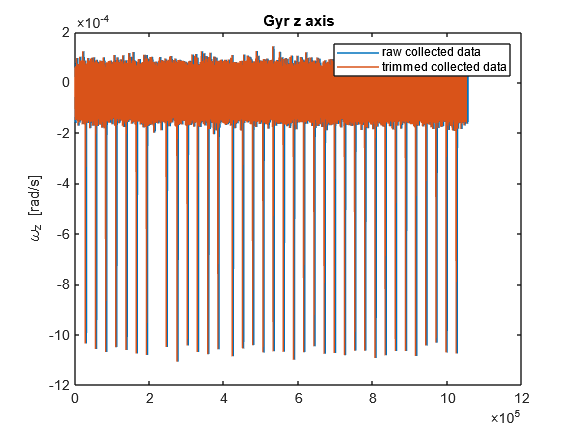

clear all;
close all;
clc;
% fig_dir = '/Users/ian/Downloads/Master Thesis/Thesis Codes/20240319_MA_TUM/Xsens/'; % to the saving folder

opts = delimitedTextImportOptions("NumVariables", 20);

% Specify range and delimiter
opts.DataLines = [15, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14", "Acc_X", "Acc_Y", "Acc_Z", "Gyr_X", "Gyr_Y", "Gyr_Z"];
opts.SelectedVariableNames = ["Acc_X", "Acc_Y", "Acc_Z", "Gyr_X", "Gyr_Y", "Gyr_Z"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var14"], "EmptyFieldRule", "auto");

% Import the data
xsens_data1 = readtable("/MATLAB Drive/Final code/2024-03-19_MTi-G-710-2A8G4-15h02-000.txt", opts);
clear opts
data1 = table2array(xsens_data1);
data2 = data1(:,6); % noisy omega z

%% 🚨🚨 Transition points
transition = 0;

if transition == 1 %Trimmed data without the transition peaks
    %% Manual trim data
    % idx = find(-0.0143 >= data1(:,6)   & data1(:,6) <= -0.0144);    
    data2([1:3001,29002:31086,57087:58532,84533:85703,111704:112799,138800:140441,166442:167714,193715:195107,221108:248257,274258:277207,303208:304553,330554:331748,357749:359769,385770:386957,412958:425571,451572:453205,479206:480297,506298:507880,533881:535217,561218:562417,588418:589946,615947:617174,643175:644779,670780:672256,698257:699544,725545:726804,752805:754195,780196:781183,807184:808860,834861:835924,861925:863361,889362:890607,916608:917714,943715:945204,971205:972341,998342:999487,1025488:1026576,1052577:end])=[];
else
    %Trimmed data maintaining the transition peaks
    data2([1:3023,1053824:end])=[];
end

%% 🚨🚨 Transition points


wz_noisy    = data2 * pi/180;   %% noisy omega z [rad/s]

figure
plot(data1(:,6)*pi/180)
hold on
plot(wz_noisy)
legend('raw collected data','trimmed collected data')
title('Gyr z axis')
ylabel('\omega_z [rad/s]')
hold off

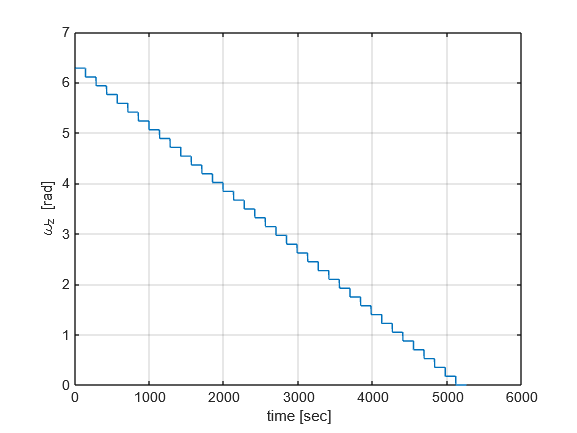

%% simulation szenario:
% An IMU mounted on a turntable which increses the rotation rates around the z-axis
% to achieve constant rotation rates while resting for 10 seconds at each
% rate value. The simulation covers both negative and positive angle
% velocity rates, i.e. from -1 rad/s --Y + 1 rad/s

% IMU parameters
f_imu     =200; % IMU sample rate in [Hz]

minRate= 2 *180;      % deg
maxRate= 0 *180;      % deg

% set up gyro rates steps 
rateSteps = linspace(minRate,maxRate,37);

% Change stop duration between 130 and 142 to have without and with
% transition periods in raw data respectively
if transition == 1
    stopDuration = 130;                  %sec
else
    stopDuration = 142;                  %sec
end

psi=[];

for i=1:length(rateSteps)
   
    gyro_tem= ones(stopDuration *f_imu ,1) * rateSteps(i);
    psi=[psi;gyro_tem];

end


t=(1/f_imu:1/f_imu:length(rateSteps)* stopDuration)' ; % considered time span for training data; here 50 s

% figure
% plot(t,psi)
% xlabel('time [sec]')
% ylabel('\omega_z [deg]')
% grid on

% convert signal from deg to rad                      
psi=psi*pi/180;                             %  [rad] (error free omega z)

% plot error-free reference signal

figure
plot(t,psi)
xlabel('time [sec]')
ylabel('\omega_z [rad]')
grid on

% % Split the data into training and testing sets
split_ratio             = 0.8; % 60% training, 20% validation, 20% testing
num_samples             = size(wz_noisy, 1);
split_idx_train         = round(split_ratio * num_samples);
split_idx_val           = round(0.8 * num_samples); 


%% split the data to training, validation and testing, including the reference data
%% Training sets
train_data          = num2cell(wz_noisy(1:split_idx_val, :),1);
train_labels        = num2cell(psi(1:split_idx_val, :),1);

% % Validation sets
% val_data            = num2cell(wz_noisy(split_idx_train+1:split_idx_val, :),1);
% val_labels          = num2cell(psi(split_idx_train+1:split_idx_val, :),1);

%% Testing sets
test_data           = (wz_noisy(split_idx_val+1:end, :))';
test_labels         = (psi(split_idx_val+1:end, :))';

%% since I need my input size to the NN to be 1, I need to change the
%% appearance of the cell array, where each cell of both data & labels
%% to be 1xsplit_idx & 1xsplit_id+1:end respectively

train_data{:}       = train_data{:}';
train_labels{:}     = train_labels{:}';

% val_data{:}         = val_data{:}';
% val_labels{:}       = val_labels{:}';

% configure neural network (NN)
numFeatures     = size(train_data, 1); % Number of features in your data
numResponses    = 1;

layers = [
    sequenceInputLayer(numFeatures)    
    fullyConnectedLayer(numResponses, 'Name', 'output')
    StrapdownRegressionLayer('1D-StrapdownRegression')
];


% Set training options with the Adam optimizer
options = trainingOptions('adam', ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 2^8, ...
    'SequenceLength', 20, ... % Adjust as needed
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.9, ...
    'LearnRateDropPeriod', 10, ...
    'Shuffle', 'every-epoch', ...  % to reduce biases in training
    'ExecutionEnvironment', 'auto', ...
    'Plots','training-progress',...
    'Verbose',1);

% Train the LSTM network
net = trainNetwork(train_data, train_labels, layers, options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:52 |         6.28 |      6.1e-11 |          0.0100 |
|       1 |          50 |       00:00:52 |         6.28 |      8.7e-10 |          0.0100 |
|       1 |         100 |       00:00:53 |         6.28 |      1.1e-09 |          0.0100 |
|       1 |         150 |       00:00:53 |         6.28 |      7.9e-11 |          0.0100 |
|       1 |         200 |       00:00:53 |         6.28 |      4.9e-09 |          0.0100 |
|       1 |         250 |       00:00:53 |         6.28 |      3.2e-10 |          0.0100 |
|       1 |         300 |       00:00:53 |         6.28 |      5.1


% Test the trained network
predicted_labels = predict(net, test_data);
predicted_labels = cumsum(predicted_labels)/f_imu;

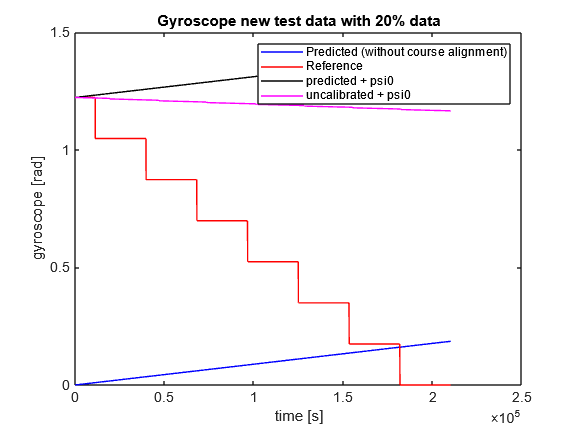

%% Course alignement and Plots

predicted_psi0  = predicted_labels + (test_labels(1,1)-predicted_labels(1,1)); % course alignment

% Test data that hasn't gone through network but still intergrated and
% course alignment done
uncalibrated_data = cumsum(test_data)/f_imu;
uncalibrated_data = uncalibrated_data + (test_labels(1,1)-uncalibrated_data(1,1)); % course alignment

%% Plots
fig1=figure;
plot(predicted_labels,'b');
hold on;
plot(test_labels, 'r');
plot(predicted_psi0,'k')
plot(uncalibrated_data,'m')
xlabel('time [s]');
ylabel('gyroscope [rad]');
legend('Predicted (without course alignment)','Reference','predicted + psi0','uncalibrated + psi0');
title('Gyroscope new test data with 20% data');

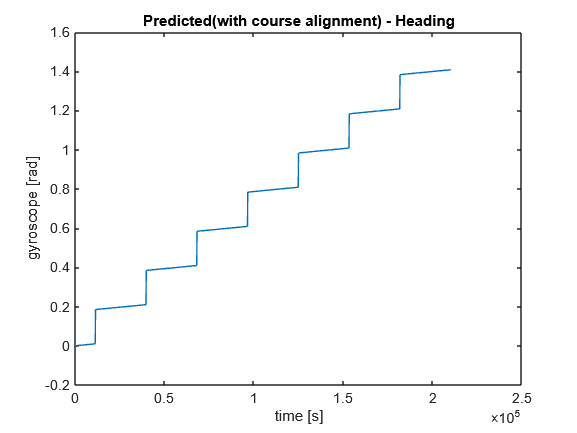

% saveas(fig1, fullfile(fig_dir,strcat('Gyroscope new test data with 20% data', '.png')));

fig2=figure;
plot(predicted_psi0 - test_labels)
xlabel('time [s]');
ylabel('gyroscope [rad]');
title('Predicted(with course alignment) - Heading');

% saveas(fig2, fullfile(fig_dir,strcat('Difference between Predicted(with course alignment) and Heading', '.png')));